# **LQR tracking simulation**

**author: Xin Lyu**

% Define parameteres and states

m = 1; % kg
k = 1 ;% N/m
b = 0.5; % Ns/m

% define weighted matrix
Q = eye(2);
R = 0.1;

A = [0,1;-1,-0.5]

A =          0    1.0000
   -1.0000   -0.5000


B = [0;1]

B =      0
     1


C = [0,0];
D = 0;
n = size(A,1);
p = size(B,2);
Ts= 0.1

Ts = 0.1000

% discretize system
sym_d = c2d(ss(A,B,C,D),Ts);
A_d = sym_d.A;
B_d = sym_d.B;

% reference value
xd = [1;0];
% Transition matrix
AD = eye(n);

% intialize state
x0 = [0;0];
x = x0;
u0 = 0;
u = u0;
P_k = Q;
% augmented state
xa = [x;xd];
Ca = [eye(n) -eye(n)];
Aa = [A_d zeros(n);zeros(n) AD]

Aa =     0.9951    0.0974         0         0
   -0.0974    0.9464         0         0
         0         0    1.0000         0
         0         0         0    1.0000


Ba = [B_d; zeros(n,1)]

Ba =     0.0049
    0.0974
         0
         0


Sa = Ca'*eye(2)*Ca

Sa =      1     0    -1     0
     0     1     0    -1
    -1     0     1     0
     0    -1     0     1


Qa = Ca'*Q*Ca

Qa =      1     0    -1     0
     0     1     0    -1
    -1     0     1     0
     0    -1     0     1



% define system steps
k_steps = 100;
x_history = zeros(n,k_steps);
x_history(:,1) = x;

u_history = zeros(p,k_steps);
u_history(:,1) = u;

% calcualte F 
for k=1:k_steps
    F = inv(R+Ba'*Sa*Ba)*Ba'*Sa*Aa;
    Sa = (Aa-Ba*F)'*Sa*(Aa-Ba*F)+(F)'*R*F+Qa;

    if k == 1;
        F_N = F;
    else
        F_N = [F;F_N];
    end

end

% simulation
for k =1:k_steps
    %calculate u
    u = -F_N((k-1)*p+1:k*p,:)*xa;
    x = A_d*x+B_d*u;
    xa = [x;xd];
    x_history(:,k+1) = x;
    u_history(:,k) = u;
end
subplot(2,1,1);
for i=1:n
    plot(x_history(i,:));
    hold;
end

Current plot held
Current plot released


legend('x1','x2');
xlim([1,k_steps]);
grid on

subplot(2,1,2);
for i = 1:p
    stairs (u_history(i,:));
    hold;
end

Current plot held


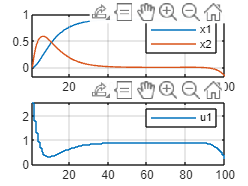

legend('u1');
xlim([1,k_steps]);
grid on